# Exemplu metoda secantei

Polinomul $x^3-2x-5$are o radacina reala, intre $x=2$ si $x=3$

## Rezolvare simbolica

syms x
z=solve(x.^3-2*x-5==0, x, 'MaxDegree',3)

$$z = \begin{array}{l} \left(\begin{array}{c} \frac{2}{3\,\sigma_{2}}+\sigma_{2}\\ -\frac{1}{3\,\sigma_{2}}-\frac{\sigma_{2}}{2}-\sigma_{1}\\ -\frac{1}{3\,\sigma_{2}}-\frac{\sigma_{2}}{2}+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,\left(\frac{2}{3\,\sigma_{2}}-\sigma_{2}\right)\,\mathrm{i}}{2}\\ \sigma_{2}={\left(\frac{\sqrt{108}\,\sqrt{643}}{108}+\frac{5}{2}\right)}^{1/3} \end{array}$$

double(z)

ans =   2.094551481542327 + 0.000000000000000i
 -1.047275740771163 + 1.135939889088928i
 -1.047275740771163 - 1.135939889088928i


Reprezentare grafica

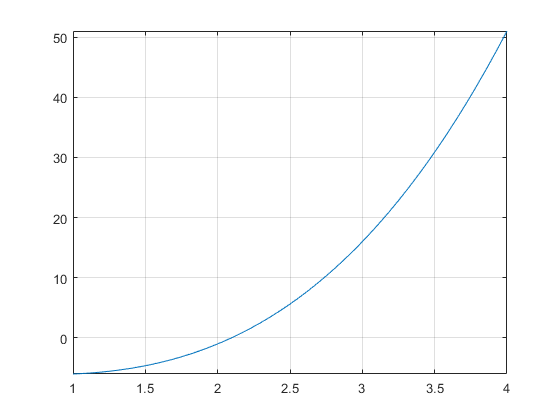

fplot(x.^3-2*x-5,[1,4]);
grid on

clear

## Rezolvare numerica 

Radacina reala

f = @(x) x^3-2*x-5;
x0 = 2; x1 = 3;
[z,ni]=secant(f,x0,x1,1e-6,0,20)

z =    2.094551481542327


ni =      6


Codul pentru metoda secantei:

function [z,ni]=secant(f,x0,x1,ea,er,Nmax)
%SECANT - metoda secantei pentru ecuatii in R
%intrare
%f - functia
%x0,x1 - valori de pornire
%ea,er - eroarea absoluta, resp eroarea relativa
%Nmax - numarul maxim de iteratii
%iesire
%z - aproximatia radacinii
%ni - numar de iteratii

if nargin<6, Nmax=50; end
if nargin<5, er=0; end
if nargin<4, ea=1e-3; end
xv=x0; fv=f(xv);
xc=x1; fc=f(xc);
for k=1:Nmax
    xn=xc-fc*(xc-xv)/(fc-fv);
    if abs(xn-xc)<ea+er*abs(xn) %succes
        z=xn;
        ni=k;
        return
    end
    %pregatesc iteratia urmatoare
    xv=xc; fv=fc;
    xc=xn; fc=feval(f,xn);
end
%esec
error('numarul maxim de iteratii depasit')
end